# Ice Wheel - Control design

clc;
s = tf('s');

### Parameters

% ice-wheel
m_w = 7.2; % kg
r_w = 0.127; % m
J_w = 1/2*m_w*r_w^2;

% chassis
m_batteries = 28*67e-3 + 0.2; % kg (cells + bms?)
m_mot_contr = 0.5; % kg
m_c = 3 + m_batteries + m_mot_contr; % kg
l_c = 0.02; % m -> COG of chassis is assumed to be in the center
h_base = 0.1;
w_base = 0.75;

% rider
m_r = 70; % kg
h_r = 1.85; % m
d_r = 0.2; % m
l_r_ = h_r * 0.55; % approximation of COG of human
l_r = l_r_ + h_base/2; % COG of rider from axel

g = 9.81; % m/s^2

% total
m_t = m_w + m_c + m_r; % kg
l_t = (l_r*m_r + l_c*m_c) / m_t; % m
J_t = 1/12*m_r*(h_r^2+d_r^2) + 1/2*m_c*l_c^2 - J_w;

disp(['Center of gravity distance from wheel axis:  ', num2str(l_t, 2), ' m']);

Center of gravity distance from wheel axis:  0.9 m


disp(['Total inertial moment of vehicle:            ', num2str(J_t, 3), ' kgm^2']);

Total inertial moment of vehicle:            20.1 kgm^2


### State Space Model

% State space model
den = (m_t + m_w + J_w/r_w^2)*(m_t*l_t^2 + J_t) - (m_t*l_t)^2; %??? Why add the m_w to m_t ??

% State matrix values
A_32 = -((m_t*l_t)^2*g)/den;
A_42 = (m_t + m_w + J_w/r_w^2)*m_t*g*l_t/den;
A = [[0, 0, 1, 0]
     [0, 0, 0, 1]
     [0, A_32, 0, 0]
     [0, A_42, 0, 0]];

% Input matrix
B_3 = -m_t*l_t/den;
B_4 = (m_t + m_w + J_w/r_w^2)/den;
B = [0; 0; B_3; B_4];

% Output matrix
C = [[1, 0, 0, 0]
     [0, 1, 0, 0]];

% Direct transmission matrix
D = [[0]
    [0]];

H = ss(A, B, C, D)

H =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -21.01       0       0
   x4       0   26.27       0       0
 
  B = 
             u1
   x1         0
   x2         0
   x3  -0.02861
   x4   0.03578
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



display(H)

H =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -21.01       0       0
   x4       0   26.27       0       0
 
  B = 
             u1
   x1         0
   x2         0
   x3  -0.02861
   x4   0.03578
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



## Motor

k_m = 1

k_m = 1

T_motor = 20e-3

T_motor = 0.0200

### PID Controller

% PID settings from paper 
K_p = 90; % (K_p)
T_0 = 1/8; % (1/K_i)
T_d = 6; % (k_d)

% T_n = K_p / K_i
% T_v = K_d / K_p

K_r = 1; % (K_p)
K_i = 8;
T_0 = 1/K_i; % (1/K_i)
T_d = 1;

G_pid  = K_p + 1/(s*T_0) + T_d*s %/(1+0.1*T_d*s)

G_pid =
 
  0.125 s^2 + 11.25 s + 1
  -----------------------
          0.125 s
 
Continuous-time transfer function.



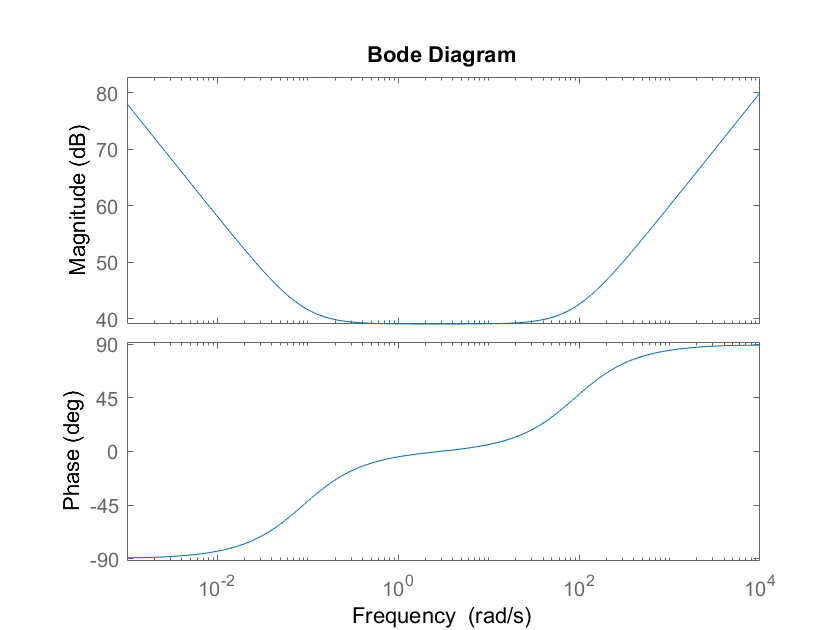


bode(G_pid)